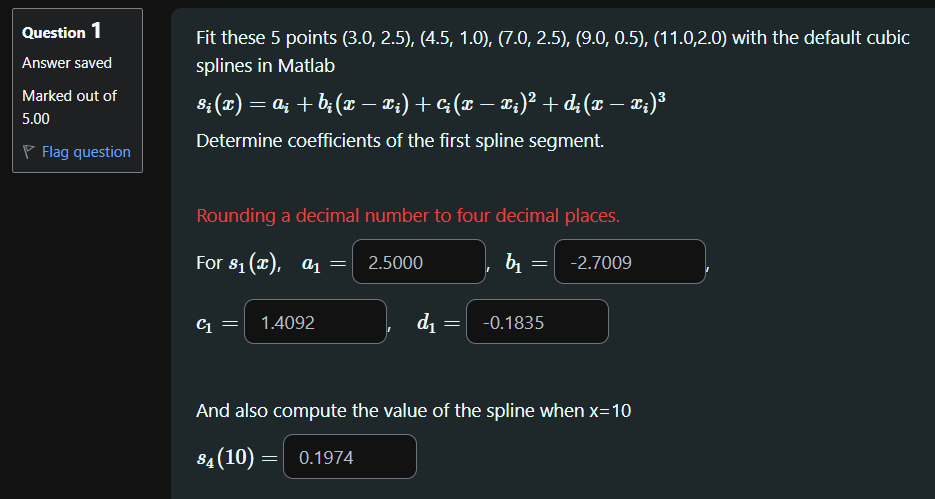

Data 

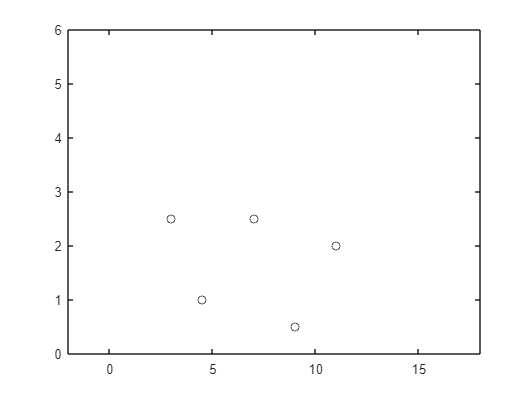

% x = [1 3 4.5 6 8 11 13 14];
% y = [2 3 3.5 2.8 4 3.5 3.4 3];

x = [3.0 4.5 7.0 9.0 11.0];
y = [2.5 1.0 2.5 0.5 2.0];

plot(x,y,'ko')
hold on
axis([-2 18 0 6])

Linear spline

xx = 3 : 0.1 : 11;
yy = interp1(x,y,xx,"linear")

yy =     2.5000    2.4000    2.3000    2.2000    2.1000    2.0000    1.9000    1.8000    1.7000    1.6000    1.5000    1.4000    1.3000    1.2000    1.1000    1.0000    1.0600    1.1200    1.1800    1.2400    1.3000    1.3600    1.4200    1.4800    1.5400    1.6000    1.6600    1.7200    1.7800    1.8400    1.9000    1.9600    2.0200    2.0800    2.1400    2.2000    2.2600    2.3200    2.3800    2.4400    2.5000    2.4000    2.3000    2.2000    2.1000    2.0000    1.9000    1.8000    1.7000    1.6000


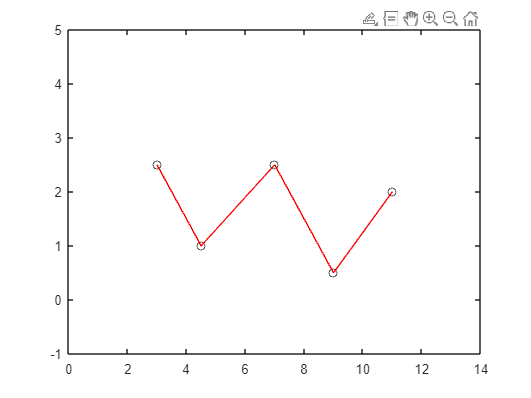



figure
plot(x,y,'ko')
hold on

plot(xx,yy,'r-')
hold off
axis([0 14 -1 5])

Quadratic spline

% xx = 1 : 0.1 : 14
% yy = quspline(x,y,xx)
% 
% plot(x,y,'ko')
% hold on
% 
% plot(xx,yy,'r-')
% hold off
% axis([-2 18 1 6])

Cubic spline (natural spline)

xx = 3 : 0.1 : 11;
yy = natspline(x,y,xx)

yy =     2.5000    2.3548    2.2108    2.0692    1.9313    1.7982    1.6711    1.5514    1.4401    1.3384    1.2477    1.1691    1.1038    1.0531    1.0181    1.0000    0.9996    1.0159    1.0474    1.0924    1.1496    1.2173    1.2941    1.3785    1.4689    1.5638    1.6617    1.7612    1.8606    1.9584    2.0532    2.1435    2.2277    2.3042    2.3717    2.4285    2.4731    2.5041    2.5199    2.5191    2.5000    2.4618    2.4057    2.3337    2.2476    2.1494    2.0408    1.9239    1.8005    1.6725


yy = interp1(x,y,xx,"spline")

yy =     2.5000    2.2438    2.0147    1.8116    1.6334    1.4789    1.3471    1.2369    1.1472    1.0769    1.0248    0.9899    0.9710    0.9672    0.9772    1.0000    1.0345    1.0795    1.1340    1.1968    1.2670    1.3433    1.4246    1.5099    1.5981    1.6881    1.7787    1.8688    1.9575    2.0434    2.1257    2.2031    2.2745    2.3389    2.3952    2.4422    2.4789    2.5041    2.5167    2.5157    2.5000    2.4688    2.4230    2.3638    2.2924    2.2101    2.1180    2.0176    1.9098    1.7961


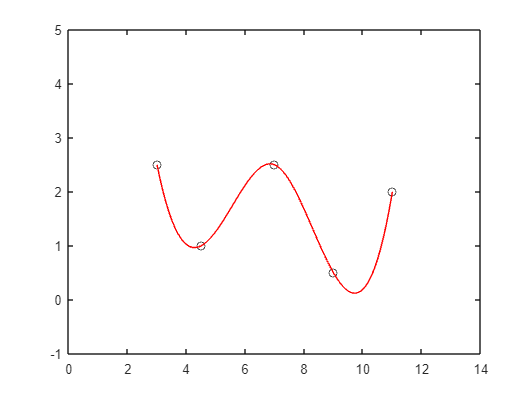

% yy2 = interp1(x,y,xx,"spline")
% pp = spline(x,y)

% 
% [~, coeffs] = unmkpp(pp);
% coeffs(2, :)
%


plot(x,y,'ko')
hold on

plot(xx,yy,'r-')
hold off
axis([0 14 -1 5])

Cubic spline (using interp1)

xx = 3 : 0.1 : 11;
% yy = natspline(x,y,xx)
yy = interp1(x,y,xx,"spline")

yy =     2.5000    2.2438    2.0147    1.8116    1.6334    1.4789    1.3471    1.2369    1.1472    1.0769    1.0248    0.9899    0.9710    0.9672    0.9772    1.0000    1.0345    1.0795    1.1340    1.1968    1.2670    1.3433    1.4246    1.5099    1.5981    1.6881    1.7787    1.8688    1.9575    2.0434    2.1257    2.2031    2.2745    2.3389    2.3952    2.4422    2.4789    2.5041    2.5167    2.5157    2.5000    2.4688    2.4230    2.3638    2.2924    2.2101    2.1180    2.0176    1.9098    1.7961


% pp2 = spline(x,y)

% 
% [~, coeffs] = unmkpp(pp2);
% coeffs(1, :)
%

plot(x,y,'ko')
hold on

plot(xx,yy,'r-')
hold off
axis([0 14 -1 5])


x_test = 10;
y_pred = spline(x,y,x_test)

y_pred = 0.1974

Cubic spline (using spline)

xx = 3 : 0.1 : 11;
% yy = natspline(x,y,xx)
yy2 = spline(x,y,xx)

yy2 =     2.5000    2.2438    2.0147    1.8116    1.6334    1.4789    1.3471    1.2369    1.1472    1.0769    1.0248    0.9899    0.9710    0.9672    0.9772    1.0000    1.0345    1.0795    1.1340    1.1968    1.2670    1.3433    1.4246    1.5099    1.5981    1.6881    1.7787    1.8688    1.9575    2.0434    2.1257    2.2031    2.2745    2.3389    2.3952    2.4422    2.4788    2.5041    2.5167    2.5157    2.5000    2.4688    2.4230    2.3638    2.2924    2.2101    2.1180    2.0176    1.9098    1.7961




plot(x,y,'ko')
hold on

plot(xx,yy,'r-')
hold off
axis([0 14 -1 5])

Cubic spline (using spline & ppval)

xx = 3 : 0.1 : 11;
cs = spline(x,y)

cs = struct with fields:
      form: 'pp'
    breaks: [3 4.5000 7 9 11]
     coefs: [4×4 double]
    pieces: 4
     order: 4
       dim: 1


yy = ppval(cs,xx)

yy =     2.5000    2.2438    2.0147    1.8116    1.6334    1.4789    1.3471    1.2369    1.1472    1.0769    1.0248    0.9899    0.9710    0.9672    0.9772    1.0000    1.0345    1.0795    1.1340    1.1968    1.2670    1.3433    1.4246    1.5099    1.5981    1.6881    1.7787    1.8688    1.9575    2.0434    2.1257    2.2031    2.2745    2.3389    2.3952    2.4422    2.4788    2.5041    2.5167    2.5157    2.5000    2.4688    2.4230    2.3638    2.2924    2.2101    2.1180    2.0176    1.9098    1.7961




plot(x,y,'ko')
hold on

plot(xx,yy,'r-')
hold off
axis([0 14 -1 5])

Cubic spline (plot each segment with different colors)

seg1 = linspace(x(1),x(2))

seg1 =     3.0000    3.0152    3.0303    3.0455    3.0606    3.0758    3.0909    3.1061    3.1212    3.1364    3.1515    3.1667    3.1818    3.1970    3.2121    3.2273    3.2424    3.2576    3.2727    3.2879    3.3030    3.3182    3.3333    3.3485    3.3636    3.3788    3.3939    3.4091    3.4242    3.4394    3.4545    3.4697    3.4848    3.5000    3.5152    3.5303    3.5455    3.5606    3.5758    3.5909    3.6061    3.6212    3.6364    3.6515    3.6667    3.6818    3.6970    3.7121    3.7273    3.7424


seg2 = linspace(x(2),x(3))

seg2 =     4.5000    4.5253    4.5505    4.5758    4.6010    4.6263    4.6515    4.6768    4.7020    4.7273    4.7525    4.7778    4.8030    4.8283    4.8535    4.8788    4.9040    4.9293    4.9545    4.9798    5.0051    5.0303    5.0556    5.0808    5.1061    5.1313    5.1566    5.1818    5.2071    5.2323    5.2576    5.2828    5.3081    5.3333    5.3586    5.3838    5.4091    5.4343    5.4596    5.4848    5.5101    5.5354    5.5606    5.5859    5.6111    5.6364    5.6616    5.6869    5.7121    5.7374


seg3 = linspace(x(3),x(4))

seg3 =     7.0000    7.0202    7.0404    7.0606    7.0808    7.1010    7.1212    7.1414    7.1616    7.1818    7.2020    7.2222    7.2424    7.2626    7.2828    7.3030    7.3232    7.3434    7.3636    7.3838    7.4040    7.4242    7.4444    7.4646    7.4848    7.5051    7.5253    7.5455    7.5657    7.5859    7.6061    7.6263    7.6465    7.6667    7.6869    7.7071    7.7273    7.7475    7.7677    7.7879    7.8081    7.8283    7.8485    7.8687    7.8889    7.9091    7.9293    7.9495    7.9697    7.9899


seg4 = linspace(x(4),x(5))

seg4 =     9.0000    9.0202    9.0404    9.0606    9.0808    9.1010    9.1212    9.1414    9.1616    9.1818    9.2020    9.2222    9.2424    9.2626    9.2828    9.3030    9.3232    9.3434    9.3636    9.3838    9.4040    9.4242    9.4444    9.4646    9.4848    9.5051    9.5253    9.5455    9.5657    9.5859    9.6061    9.6263    9.6465    9.6667    9.6869    9.7071    9.7273    9.7475    9.7677    9.7879    9.8081    9.8283    9.8485    9.8687    9.8889    9.9091    9.9293    9.9495    9.9697    9.9899


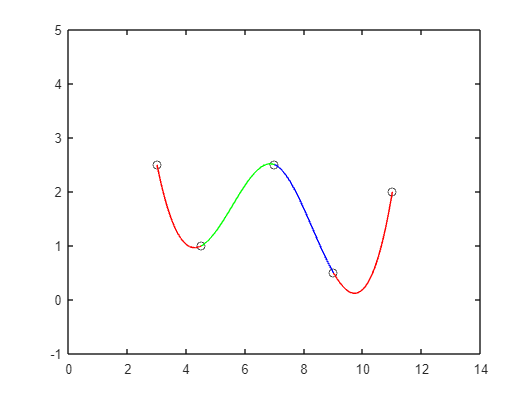

% seg5 = linspace(x(5),x(6))
% seg6 = linspace(x(6),x(7))
% seg7 = linspace(x(7),x(8))

yseg1 = spline(x,y,seg1);
yseg2 = spline(x,y,seg2);
yseg3 = spline(x,y,seg3);
yseg4 = spline(x,y,seg4);
% yseg5 = spline(x,y,seg5);
% yseg6 = spline(x,y,seg6);
% yseg7 = spline(x,y,seg7);

plot(x,y,'ko')

hold on
plot(seg1,yseg1,'r-')
plot(seg2,yseg2,'g-')
plot(seg3,yseg3,'b-')
plot(seg4,yseg4,'r-')
% plot(seg5,yseg5,'g-')
% plot(seg6,yseg6,'b-')
% plot(seg7,yseg7,'r-')
hold off

axis([0 14 -1 5])